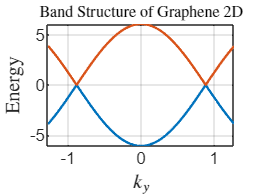

gamma_0 = 3.033;
s_0=0.129;
epsilon_2p=0.0;
a=2.46;
p=pi;
kx=0.0;

E1=[];E2=[];

for x=-(p)/a:0.01:(p)/a
    fk=exp((1i*x*a)/3^(1/2))+exp((-1i*x*a)/2*3^(1/2))*cos((kx*a)/2);
    fkcc=exp((-1i*x*a)/3^(1/2))+exp((1i*x*a)/2*3^(1/2))*cos((kx*a)/2);
    H1=[epsilon_2p -gamma_0*fk; -gamma_0*fkcc epsilon_2p];
    S1=[1 s_0*fk; s_0*fkcc 1];

    Energies=eig(H1);

    E1(end+1)=Energies(1);
    E2(end+1)=Energies(2);
    
end

x=-(p)/a:0.01:(p)/a;
y=-(p)/a:0.01:(p)/a;
figure; hold on;
xlabel('$k_y$','interpreter','latex','FontSize',10);
ylabel('Energy','interpreter','latex','FontSize',10);
title('Band Structure of Graphene 2D','Interpreter','latex','FontSize',8);
box on;
grid on;
plot(x,E1,'LineWidth',1.2,'MarkerSize',5,'MarkerEdgeColor','m'); hold on;
plot(x,E2,'LineWidth',1.2,'MarkerSize',5,'MarkerEdgeColor','m'); hold on;

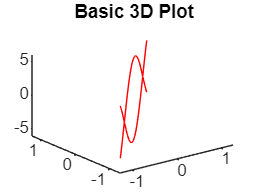



figure;
plot3(x, y, E1, 'r');
hold on;
plot3(x, y, E2, 'r');
title('Basic 3D Plot');